# Taller 2: Redes Neuronales Multicapa (MLP) y Backpropagation

**Asignatura:** Inteligencia Computacional Aplicada

**Docente:** Cesar Andrey Perdomo Charry

**Estudiante:** Sergio Santiago Duarte Rojas

## 1. Fundamento teórico: Perceptrón Multicapa (MLP) y Backpropagation

**¿Por qué una sola capa no basta?** En el Taller 1 vimos que el Perceptrón Simple y Adaline solo pueden resolver problemas **linealmente separables**. El problema XOR es el ejemplo clásico de un problema que **no** lo es, y por eso requiere una arquitectura con al menos una **capa oculta**.

**Arquitectura del MLP**

Una red multicapa se organiza en capas $k = 1,\dots,L$. Cada neurona $j$ de la capa $k$ calcula:


$$net_j^{(k)} = \sum_i w_{ji}^{(k)} a_i^{(k-1)} + b_j^{(k)}, \qquad a_j^{(k)}
 = f\left(net_j^{(k)}\right)$$


donde $a^{(0)} = x$ (la entrada) y $f$ es la función de activación de la capa (sigmoidal, tangente hiperbólica o ReLU en este taller).

**Algoritmo de Backpropagation**

El error se mide típicamente como error cuadrático medio:


$$E = \frac{1}{2}\sum \left(d(x) - Y(x)\right)^2$$


El algoritmo ajusta los pesos por **descenso de gradiente**, propagando el error desde la salida hacia las capas ocultas:


$$\delta^{(L)} = \left(d(x) - Y(x)\right) \odot f'\left(net^{(L)}\right) \qquad
 \text{(capa de salida)}$$



$$\delta^{(k)} = \left(W^{(k+1)T}\delta^{(k+1)}\right) \odot f'\left(net^{(k)}\right)
 \qquad \text{(capas ocultas)}$$



$$W^{(k)} \leftarrow W^{(k)} + \eta\, \delta^{(k)} \left(a^{(k-1)}\right)^T,
 \qquad b^{(k)} \leftarrow b^{(k)} + \eta\, \delta^{(k)}$$


donde $\eta$ es la tasa de aprendizaje. Opcionalmente se agrega un **término de momento** $\beta$ que suaviza la trayectoria de convergencia usando el incremento de la iteración anterior:


$$\Delta W^{(k)} \leftarrow \eta\, \delta^{(k)} \left(a^{(k-1)}\right)^T +
 \beta\, \Delta W^{(k)}_{\text{anterior}}$$


**Funciones de activación más comunes**

- **Sigmoidal:** $f(net)=\dfrac{1}{1+e^{-net}}$, con $f'(net)=f(net)(1-f(net))$. Satura para valores extremos, lo que puede ralentizar el aprendizaje (*vanishing gradient*).

- **Tangente hiperbólica:** $f(net)=\tanh(net)$, con $f'(net)=1-\tanh^2(net)$. Centrada en cero, suele converger algo más rápido que la sigmoidal.

- **ReLU:** $f(net)=\max(0,net)$, con $f'(net)=1$ si $net>0$ y $0$ en caso contrario. Evita la saturación pero puede "apagar" neuronas (*dying ReLU*).

**Referencias y lecturas complementarias**

- Rumelhart, D. E., Hinton, G. E., & Williams, R. J. (1986). Learning representations by back-propagating errors. *Nature*, 323(6088), 533-536.  [doi.org/10.1038/323533a0](https://doi.org/10.1038/323533a0)

- Haykin, S. (2009). *Neural Networks and Learning Machines* (3rd ed.), Capítulo 4: Multilayer Perceptrons. Pearson.

- Goodfellow, I., Bengio, Y., & Courville, A. (2016). *Deep Learning*, Capítulo 6. [deeplearningbook.org](https://www.deeplearningbook.org/) (disponible gratis en línea)

- Nielsen, M. (2015). *Neural Networks and Deep Learning*, Capítulo 2 (backpropagation, con derivación paso a paso).  [neuralnetworksanddeeplearning.com/chap2.html](http://neuralnetworksanddeeplearning.com/chap2.html) (libro gratuito en línea)

- MathWorks. [Multilayer Shallow Neural Networks and Backpropagation Training](https://www.mathworks.com/help/deeplearning/ug/multilayer-shallow-neural-networks-and-backpropagation-training.html)

clear; clc; close all;

## 2. Parámetros del modelo (totalmente parametrizable)

**Qué se espera en esta sección:** una estructura `cfg` editable que controla la arquitectura de la red y el proceso de entrenamiento. No requiere que complete código aquí, pero **sí** deberá modificar estos valores (número de neuronas ocultas, función de activación, tasa de aprendizaje, etc.) en los distintos numerales del taller para comparar arquitecturas.

Se agregan a `cfg` el criterio de parada por épocas sin mejora (`patience`), el umbral de decisión, la fracción de validación, la escala de los pesos iniciales y las rutas de los datos. `act_hidden` acepta una celda con una activación por capa oculta. Las tablas de resultados de los numerales 3 a 6 se acumulan en `R3` a `R6`.

cfg.n_inputs      = 2;            % número de entradas
cfg.hidden_layers = [4];          % neuronas por capa oculta, ej. [4 3]
cfg.n_outputs     = 1;            % número de salidas
cfg.act_hidden    = 'sigmoid';    % 'sigmoid' | 'tanh' | 'relu'
cfg.act_output    = 'sigmoid';    % 'sigmoid' | 'tanh' | 'relu' | 'linear'
cfg.eta           = 0.3;          % tasa de aprendizaje (eta)
cfg.momentum      = 0.0;          % coeficiente de momento (beta), 0-1
cfg.max_epochs    = 5000;
cfg.target_error  = 1e-3;
cfg.patience      = 0;            % épocas sin mejora en validación antes de parar, 0 desactiva
cfg.threshold     = 0.5;          % umbral de decisión con una sola salida
cfg.val_fraction  = 0.2;          % parte del entrenamiento que se reserva para validación
cfg.init_scale    = 0.5;          % escala de los pesos iniciales, W = randn * init_scale
cfg.seed          = 1;
cfg.datos         = struct('iris', 'iris.dat', 'wine', 'wine.data', 'wdbc', 'wdbc.data', ...
                           'banknote', 'data_banknote_authentication.txt');
% Perceptrón y Adaline del Taller 1, con sus mismos parámetros, para las comparaciones.
cfgP = struct('threshold', 0.5, 'learning_rule', 'perceptron_alpha', 'alpha', 0.1, ...
              'max_epochs', 100, 'init_scale', 0.5, 'n_inputs', 2, 'seed', 1);
cfgA = struct('threshold', 0.5, 'alpha', 0.05, 'max_epochs', 200, 'target_mse', 1e-3, ...
              'init_scale', 0.5, 'n_inputs', 2, 'seed', 1);
cfg_base = cfg;

paleta = [0.00 0.35 0.64; 0.85 0.37 0.01; 0.00 0.55 0.40; 0.45 0.20 0.55; 0.80 0.65 0.10; 0.40 0.45 0.50];

rng(cfg.seed);

## 3. Datos de entrenamiento

**Teoría breve:** el problema XOR asigna salida 1 cuando exactamente una de las dos entradas es 1, y 0 en caso contrario. No existe una única línea recta (hiperplano) que separe las clases, por lo que un Perceptrón simple (Taller 1) **no puede** resolverlo; de ahí la necesidad de la capa oculta.

**Qué se espera en esta sección:** las matrices `X` (patrones, una fila por patrón) y `D` (salidas deseadas) listas para entrenar.

X = [0 0; 0 1; 1 0; 1 1];   % cada FILA es un patrón de entrada
D = [0; 1; 1; 0];           % salida deseada d(x)

## 4. Inicialización de la red — función `init_mlp`

**Teoría:** los pesos se inicializan con valores aleatorios **pequeños** (no en cero) para romper la simetría entre neuronas de una misma capa; si todas partieran del mismo valor, aprenderían siempre lo mismo. Los sesgos (bias) usualmente se inicializan en cero.

**Qué se espera en esta sección:** la función debe devolver una estructura `net` con:

- `net.W{k}` : matriz de pesos de la capa $k$ (tamaño: neuronas_k x neuronas_{k-1})

- `net.b{k}` : vector de sesgos de la capa $k$

- `net.dW_prev{k}`, `net.db_prev{k}` : incrementos anteriores en ceros, para el término de momento

net = init_mlp(cfg);

## 5. Propagación hacia adelante — función `forward_mlp`

**Teoría:** dado un patrón de entrada, se calcula la salida de cada capa aplicando la fórmula $a^{(k)} = f\left(W^{(k)}a^{(k-1)}+b^{(k)}\right)$ de manera secuencial hasta llegar a la capa de salida.

**Qué se espera en esta sección:** la función debe devolver la salida `y` de la red y una estructura `cache` con los valores intermedios (`cache.a` y `cache.netv` de cada capa), necesarios para el paso de backpropagation.

## 6. Retropropagación del error — función `backward_mlp`

**Teoría:** implemente las fórmulas de la Sección 1 (deltas de salida y de las capas ocultas, y la actualización de pesos con momento opcional).

**Qué se espera en esta sección:** la función debe actualizar y devolver `net` con los pesos ya ajustados para el patrón actual.

## 7. Funciones de activación y sus derivadas

**Qué se espera en esta sección:** `activation` ya está completa; usted debe completar `activation_deriv`, que se usa dentro de `backward_mlp` para calcular $f'(net)$.

## 8. Entrenamiento (ciclo de épocas)

**Teoría:** en el **aprendizaje en línea** (*online*), los pesos se actualizan patrón por patrón (a diferencia del aprendizaje por lotes, donde se acumula el gradiente de todo el conjunto antes de actualizar). Se recorre el conjunto de entrenamiento en orden aleatorio en cada época para evitar sesgos de orden.

**Qué se espera en esta sección:** al ejecutar este bloque, el error cuadrático medio (`error_hist`) debe decrecer época a época hasta alcanzar `cfg.target_error` o completar `cfg.max_epochs`. Si el error no baja, revise las fórmulas completadas en las secciones 4-7.

error_hist = zeros(cfg.max_epochs, 1);

for epoch = 1:cfg.max_epochs
    epoch_error = 0;
    idx = randperm(size(X, 1));

    for p = idx
        x = X(p, :)';
        d = D(p, :)';

        % ---- forward pass ----
        [y, cache] = forward_mlp(net, x, cfg);

        % ---- backward pass (backpropagation) + actualización ----
        net = backward_mlp(net, cache, x, d, cfg);

        epoch_error = epoch_error + 0.5 * sum((d - y).^2);
    end

    error_hist(epoch) = epoch_error / size(X, 1);

    if error_hist(epoch) <= cfg.target_error
        fprintf('Convergencia en la época %d (error = %.6f)\n', epoch, error_hist(epoch));
        error_hist = error_hist(1:epoch);
        break;
    end
end

Convergencia en la época 4294 (error = 0.001000)


## 9. Resultados y visualización

**Qué se espera en esta sección:** una curva de error decreciente y, para el caso XOR, salidas cercanas a 0 o 1 que coincidan con la columna `d` para cada patrón. Compare estos resultados con los obtenidos en el Taller 1 (Perceptrón/Adaline) para el mismo problema: allí el modelo **no** debía poder converger en XOR.

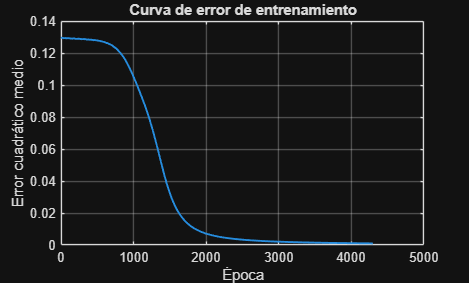

figure;
plot(error_hist, 'LineWidth', 1.4);
xlabel('Época'); ylabel('Error cuadrático medio');
title('Curva de error de entrenamiento');
grid on;


fprintf('\nResultados finales:\n');


Resultados finales:


for p = 1:size(X, 1)
    y = forward_mlp(net, X(p, :)', cfg);
    fprintf('x = [%s]  ->  y = %.4f   (d = %g)\n', num2str(X(p, :)), y, D(p, :));
end

x = [0  0]  ->  y = 0.0233   (d = 0)
x = [0  1]  ->  y = 0.9576   (d = 1)
x = [1  0]  ->  y = 0.9577   (d = 1)
x = [1  1]  ->  y = 0.0621   (d = 0)


## 9.1 Numeral 3, XOR de 2 y 3 entradas frente al Perceptrón y el Adaline del Taller 1

La XOR de 3 entradas vale 1 cuando un número impar de entradas vale 1. Se entrena el MLP con tres tamaños de capa oculta y se repite con cinco semillas. El Perceptrón y el Adaline usan las mismas funciones y parámetros del Taller 1, definidos en la sección 2.

semillas = 1:5;
cv = false(numel(semillas), 1);
ocultas_xor = {[2], [4], [8]};
R3 = table();
for n_in = [2 3]
    [X, D] = xor_data(n_in);
    cfgP.n_inputs = n_in;  cfgA.n_inputs = n_in;
    ep = zeros(numel(semillas), 1);  acc = ep;
    for i = 1:numel(semillas), s = semillas(i);
        rng(s);  [W, b, ep(i)] = train_perceptron(X, D, cfgP);
        acc(i) = accuracy_of(X, D, W, b, cfgP.threshold);
    end
    R3 = [R3; table(n_in, {'Perceptrón'}, {'ninguna'}, mean(ep), 100*mean(ep < cfgP.max_epochs), mean(acc), ...
          'VariableNames', {'Entradas', 'Modelo', 'Ocultas', 'Epocas', 'Convergio', 'Exactitud'})];
    for i = 1:numel(semillas), s = semillas(i);
        rng(s);  [W, b, mse_hist] = train_adaline(X, D, cfgA);
        ep(i) = numel(mse_hist);  acc(i) = accuracy_of(X, D, W, b, cfgA.threshold);
    end
    R3 = [R3; table(n_in, {'Adaline'}, {'ninguna'}, mean(ep), 100*mean(ep < cfgA.max_epochs), mean(acc), ...
          'VariableNames', {'Entradas', 'Modelo', 'Ocultas', 'Epocas', 'Convergio', 'Exactitud'})];
    for h = 1:numel(ocultas_xor)
        cfg = cfg_base;  cfg.n_inputs = n_in;  cfg.hidden_layers = ocultas_xor{h};
        for i = 1:numel(semillas), s = semillas(i);
            cfg.seed = s;
            [net, hist] = train_mlp(X, D, [], [], cfg);
            ep(i) = hist.epochs;  cv(i) = hist.convergio;  acc(i) = accuracy_mlp(net, X, D, cfg);
        end
        R3 = [R3; table(n_in, {'MLP'}, {mat2str(ocultas_xor{h})}, mean(ep), 100*mean(cv), mean(acc), ...
              'VariableNames', {'Entradas', 'Modelo', 'Ocultas', 'Epocas', 'Convergio', 'Exactitud'})];
    end
    cfg = cfg_base;  cfg.n_inputs = n_in;  cfg.hidden_layers = [4];  cfg.momentum = 0.9;
    for i = 1:numel(semillas), s = semillas(i);
        cfg.seed = s;  [net, hist] = train_mlp(X, D, [], [], cfg);
        ep(i) = hist.epochs;  cv(i) = hist.convergio;  acc(i) = accuracy_mlp(net, X, D, cfg);
    end
    R3 = [R3; table(n_in, {'MLP, momento 0.9'}, {'4'}, mean(ep), 100*mean(cv), mean(acc), ...
          'VariableNames', {'Entradas', 'Modelo', 'Ocultas', 'Epocas', 'Convergio', 'Exactitud'})];
end
cfg = cfg_base;
R3

R3 = 12×6 table
    Entradas           Modelo             Ocultas      Epocas    Convergio    Exactitud
    ________    ____________________    ___________    ______    _________    _________

       2        {'Perceptrón'      }    {'ninguna'}       100         0           30   
       2        {'Adaline'         }    {'ninguna'}       200         0           30   
       2        {'MLP'             }    {'2'      }      4406        80          100   
       2        {'MLP'             }    {'4'      }    4116.6       100          100   
       2        {'MLP'             }    {'8'      }      3443       100          100   
       2        {'MLP, momento 0.9'}    {'4'      }     435.8       100          100   
       3        {'Perceptrón'      }    {'ninguna'}       100         0         47.5   
       3        {'Adaline'         }    {'ninguna'}       200         0           50   
       3        {'MLP'             }    {'2'      }      5000         0         62.5   
       3       

## 9.2 Momento y función de activación sobre la XOR

Con cuatro neuronas ocultas se varía el coeficiente de momento y la función de activación de la capa oculta, cinco semillas por configuración. La última fila de cada bloque usa dos capas ocultas con una activación distinta en cada una.

momentos = [0 0.5 0.9];
activaciones = {'sigmoid', 'tanh', 'relu'};
R3b = table();
for n_in = [2 3]
    [X, D] = xor_data(n_in);
    for m = momentos
        cfg = cfg_base;  cfg.n_inputs = n_in;  cfg.hidden_layers = [4];  cfg.momentum = m;
        ep = zeros(numel(semillas), 1);  acc = ep;
        for i = 1:numel(semillas), s = semillas(i);
            cfg.seed = s;  [net, hist] = train_mlp(X, D, [], [], cfg);
            ep(i) = hist.epochs;  cv(i) = hist.convergio;  acc(i) = accuracy_mlp(net, X, D, cfg);
        end
        R3b = [R3b; table(n_in, {'sigmoid'}, m, mean(ep), 100*mean(cv), mean(acc), ...
               'VariableNames', {'Entradas', 'Activacion', 'Momento', 'Epocas', 'Convergio', 'Exactitud'})];
    end
    for a = 2:3
        cfg = cfg_base;  cfg.n_inputs = n_in;  cfg.hidden_layers = [4];  cfg.act_hidden = activaciones{a};
        ep = zeros(numel(semillas), 1);  acc = ep;
        for i = 1:numel(semillas), s = semillas(i);
            cfg.seed = s;  [net, hist] = train_mlp(X, D, [], [], cfg);
            ep(i) = hist.epochs;  cv(i) = hist.convergio;  acc(i) = accuracy_mlp(net, X, D, cfg);
        end
        R3b = [R3b; table(n_in, activaciones(a), 0, mean(ep), 100*mean(cv), mean(acc), ...
               'VariableNames', {'Entradas', 'Activacion', 'Momento', 'Epocas', 'Convergio', 'Exactitud'})];
    end
    cfg = cfg_base;  cfg.n_inputs = n_in;  cfg.hidden_layers = [4 4];  cfg.act_hidden = {'tanh', 'sigmoid'};  cfg.momentum = 0.9;
    ep = zeros(numel(semillas), 1);  acc = ep;
    for i = 1:numel(semillas), s = semillas(i);
        cfg.seed = s;  [net, hist] = train_mlp(X, D, [], [], cfg);
        ep(i) = hist.epochs;  cv(i) = hist.convergio;  acc(i) = accuracy_mlp(net, X, D, cfg);
    end
    R3b = [R3b; table(n_in, {'[4 4], tanh y sigmoid'}, 0.9, mean(ep), 100*mean(cv), mean(acc), ...
           'VariableNames', {'Entradas', 'Activacion', 'Momento', 'Epocas', 'Convergio', 'Exactitud'})];
end
cfg = cfg_base;
R3b

R3b = 12×6 table
    Entradas           Activacion            Momento    Epocas    Convergio    Exactitud
    ________    _________________________    _______    ______    _________    _________

       2        {'sigmoid'              }        0      4116.6       100          100   
       2        {'sigmoid'              }      0.5      2087.6       100          100   
       2        {'sigmoid'              }      0.9       435.8       100          100   
       2        {'tanh'                 }        0       879.8       100          100   
       2        {'relu'                 }        0      2416.4        60           90   
       2        {'[4 4], tanh y sigmoid'}      0.9         149       100          100   
       3        {'sigmoid'              }        0      4187.8        40           75   
       3        {'sigmoid'              }      0.5      4281.2        20           95   
       3        {'sigmoid'              }      0.9      1231.4       100          100   
   

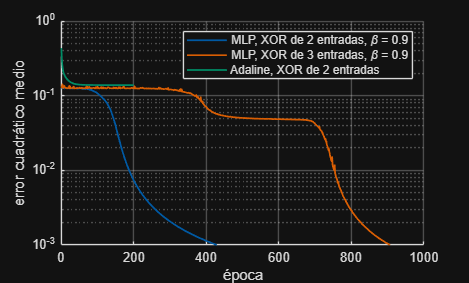


figure; colororder(paleta); hold on
for n_in = [2 3]
    [X, D] = xor_data(n_in);
    cfg = cfg_base;  cfg.n_inputs = n_in;  cfg.hidden_layers = [4];  cfg.momentum = 0.9;
    [~, hist] = train_mlp(X, D, [], [], cfg);
    plot(hist.train, 'LineWidth', 1.3, 'DisplayName', sprintf('MLP, XOR de %d entradas, \\beta = 0.9', n_in))
end
cfgA.n_inputs = 2;  rng(1);  [~, ~, mse_hist] = train_adaline(xor_data(2), [0; 1; 1; 0], cfgA);
plot(mse_hist, 'LineWidth', 1.3, 'DisplayName', 'Adaline, XOR de 2 entradas')
set(gca, 'YScale', 'log'); grid on; legend; xlabel('época'); ylabel('error cuadrático medio')

cfg = cfg_base;

## 10. Numeral 4, clasificación multiclase con Iris

Tres salidas con codificación uno contra el resto y decisión por la mayor salida. Partición 70-30, y dentro del 70 se reserva una quinta parte como validación para la curva de error, de modo que la prueba no interviene en el entrenamiento. Se prueban tres arquitecturas de una capa, una de dos capas y tres tasas de aprendizaje.

[X_iris, D_iris] = load_dataset('iris', cfg);
[Xtr, Dtr, Xva, Dva, Xte, Dte] = split_train_val_test(X_iris, D_iris, 0.7, cfg);
n_cls = numel(unique(D_iris));
Ttr = onehot(Dtr, n_cls);  Tva = onehot(Dva, n_cls);
ocultas_iris = {[3], [6], [12], [8 4]};
etas_iris = [0.05 0.1 0.3];
cfg = cfg_base;  cfg.n_inputs = size(X_iris, 2);  cfg.n_outputs = n_cls;  cfg.max_epochs = 1000;
n_arq = numel(ocultas_iris);  n_eta = numel(etas_iris);
R4 = table();  curvas = cell(n_arq, n_eta);  confusiones = cell(n_arq, n_eta);
for h = 1:n_arq
    for e = 1:n_eta
        cfg.hidden_layers = ocultas_iris{h};  cfg.eta = etas_iris(e);
        tic;  [net, hist] = train_mlp(Xtr, Ttr, Xva, Tva, cfg);  t = toc;
        pred = predict_mlp(net, Xte, cfg);
        confusiones{h, e} = accumarray([Dte(:) pred(:)], 1, [n_cls n_cls]);
        curvas{h, e} = hist;
        R4 = [R4; table({mat2str(ocultas_iris{h})}, etas_iris(e), hist.epochs, t, hist.train(end), hist.val(end), 100*mean(pred == Dte), ...
              'VariableNames', {'Ocultas', 'Eta', 'Epocas', 'Segundos', 'MSE_entrenamiento', 'MSE_validacion', 'Exactitud'})];
    end
end
R4

R4 = 12×7 table
     Ocultas     Eta     Epocas    Segundos    MSE_entrenamiento    MSE_validacion    Exactitud
    _________    ____    ______    ________    _________________    ______________    _________

    {'3'    }    0.05     1000      2.8372          0.015898           0.030187        95.556  
    {'3'    }     0.1     1000      2.7953          0.011433           0.037483        97.778  
    {'3'    }     0.3     1000      3.2819          0.010604           0.061981        97.778  
    {'6'    }    0.05     1000      3.1009          0.016622           0.030508        95.556  
    {'6'    }     0.1     1000      3.2775          0.011518           0.034819        97.778  
    {'6'    }     0.3     1000       2.997         0.0066021           0.044385        97.778  
    {'12'   }    0.05     1000      2.8956          0.016676            0.02869        95.556  
    {'12'   }     0.1     1000      2.9702           0.01172           0.034692        97.778  
    {'12'   }     0.3  

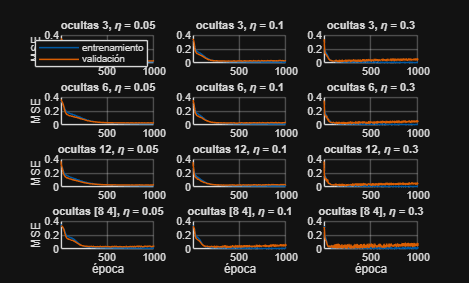


figure; colororder(paleta)
for h = 1:n_arq
    for e = 1:n_eta
        subplot(n_arq, n_eta, (h-1)*n_eta + e); hold on
        plot(curvas{h, e}.train, 'LineWidth', 1.1); plot(curvas{h, e}.val, 'LineWidth', 1.1)
        title(sprintf('ocultas %s, \\eta = %g', mat2str(ocultas_iris{h}), etas_iris(e)), 'FontSize', 8)
        grid on; xlim([1 cfg.max_epochs]); ylim([0 0.4])
        if h == n_arq, xlabel('época'); end
        if e == 1, ylabel('MSE'); end
        if h == 1 && e == 1, legend('entrenamiento', 'validación', 'Location', 'northeast'); end
    end
end


% La mejor configuración se elige por el error de validación, no por la prueba.
[~, mejor] = min(R4.MSE_validacion);
hm = ceil(mejor / n_eta);  em = mod(mejor - 1, n_eta) + 1;
Confusion_mejor = array2table(confusiones{hm, em}, 'RowNames', {'setosa', 'versicolor', 'virginica'}, ...
    'VariableNames', {'pred_setosa', 'pred_versicolor', 'pred_virginica'})

Confusion_mejor = 3×3 table
                  pred_setosa    pred_versicolor    pred_virginica
                  ___________    _______________    ______________

    setosa            14                0                  0      
    versicolor         0               11                  2      
    virginica          0                0                 18      



R4_confusiones = table();
for h = 1:n_arq
    for e = 1:n_eta
        C = confusiones{h, e};
        R4_confusiones = [R4_confusiones; table({mat2str(ocultas_iris{h})}, etas_iris(e), C(1,1), C(1,2), C(1,3), C(2,1), C(2,2), C(2,3), C(3,1), C(3,2), C(3,3), ...
            'VariableNames', {'Ocultas', 'Eta', 'se_se', 'se_ve', 'se_vi', 've_se', 've_ve', 've_vi', 'vi_se', 'vi_ve', 'vi_vi'})];
    end
end
R4_confusiones

R4_confusiones = 12×11 table
     Ocultas     Eta     se_se    se_ve    se_vi    ve_se    ve_ve    ve_vi    vi_se    vi_ve    vi_vi
    _________    ____    _____    _____    _____    _____    _____    _____    _____    _____    _____

    {'3'    }    0.05     14        0        0        0       11        2        0        0       18  
    {'3'    }     0.1     14        0        0        0       12        1        0        0       18  
    {'3'    }     0.3     14        0        0        0       12        1        0        0       18  
    {'6'    }    0.05     14        0        0        0       11        2        0        0       18  
    {'6'    }     0.1     14        0        0        0       12        1        0        0       18  
    {'6'    }     0.3     14        0        0        0       12        1        0        0       18  
    {'12'   }    0.05     14        0        0        0       11        2        0        0       18  
    {'12'   }     0.1     14        0      

## 11. Numeral 5, Wine, Breast Cancer Wisconsin y billetes por particiones

Se generan las particiones 60-40, 70-30, 80-20 y 90-10 con la misma función del Taller 1 y se entrena el MLP, el Perceptrón y el Adaline sobre cada una. La parada temprana del MLP vigila una quinta parte del entrenamiento y la exactitud se mide sobre la prueba, que no interviene. Wine tiene tres clases, así que el Perceptrón y el Adaline se entrenan con una neurona por clase y deciden por la mayor suma ponderada.

proporciones = [0.6 0.7 0.8 0.9];
conjuntos = {'wine', 'wdbc', 'banknote'};
nombres_conjuntos = {'Wine', 'Breast Cancer', 'Billetes'};
R5 = table();
for c = 1:numel(conjuntos)
    [Xd, Dd] = load_dataset(conjuntos{c}, cfg_base);
    n_clases = numel(unique(Dd));
    for r = proporciones
        [Xtr, Dtr, Xva, Dva, Xte, Dte] = split_train_val_test(Xd, Dd, r, cfg_base);
        cfg = cfg_base;  cfg.n_inputs = size(Xtr, 2);  cfg.max_epochs = 500;  cfg.patience = 30;
        if n_clases > 2
            cfg.n_outputs = n_clases;  Ttr = onehot(Dtr, n_clases);  Tva = onehot(Dva, n_clases);
        else
            cfg.n_outputs = 1;  Ttr = Dtr;  Tva = Dva;
        end
        cfg.hidden_layers = [8];
        tic;  [net, hist] = train_mlp(Xtr, Ttr, Xva, Tva, cfg);  t_mlp = toc;
        acc_mlp = 100*mean(predict_mlp(net, Xte, cfg) == Dte);

        Xtr_lineal = [Xtr; Xva];  Dtr_lineal = [Dtr; Dva];
        cfgP.n_inputs = size(Xtr, 2);  cfgA.n_inputs = size(Xtr, 2);
        tic;  [acc_p, ep_p] = one_vs_rest(Xtr_lineal, Dtr_lineal, Xte, Dte, cfgP, 'perceptron');  t_p = toc;
        tic;  [acc_a, ep_a] = one_vs_rest(Xtr_lineal, Dtr_lineal, Xte, Dte, cfgA, 'adaline');     t_a = toc;

        R5 = [R5; table(conjuntos(c), r, acc_mlp, hist.best_epoch, t_mlp, acc_p, ep_p, t_p, acc_a, ep_a, t_a, ...
              'VariableNames', {'Conjunto', 'Proporcion', 'MLP', 'Epocas_MLP', 'Seg_MLP', 'Perceptron', 'Epocas_P', 'Seg_P', 'Adaline', 'Epocas_A', 'Seg_A'})];
    end
end
cfg = cfg_base;
R5

R5 = 12×11 table
      Conjunto      Proporcion     MLP      Epocas_MLP    Seg_MLP    Perceptron    Epocas_P      Seg_P      Adaline    Epocas_A     Seg_A  
    ____________    __________    ______    __________    _______    __________    ________    _________    _______    ________    ________

    {'wine'    }       0.6        98.592       119        0.39705      95.775         52       0.0064474    97.183       200       0.018659
    {'wine'    }       0.7        98.113       150        0.57099      92.453         32       0.0053714    96.226       200       0.018133
    {'wine'    }       0.8           100       118        0.53654      94.444         25       0.0044559    97.222       200       0.018098
    {'wine'    }       0.9        94.444       121        0.60468         100         35        0.002948    94.444       200       0.020478
    {'wdbc'    }       0.6        97.368        52        0.70951      96.053        100       0.0095341    95.175       200       0.018511
  

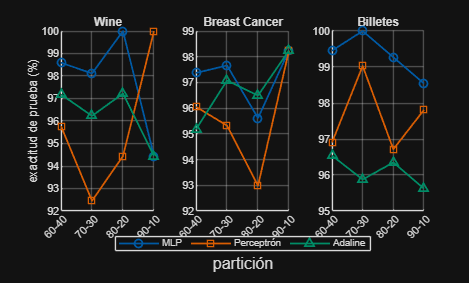


figure; colororder(paleta)
tl = tiledlayout(1, numel(conjuntos), 'TileSpacing', 'compact');
for c = 1:numel(conjuntos)
    nexttile; hold on
    m = strcmp(R5.Conjunto, conjuntos{c});
    plot(proporciones, R5.MLP(m), '-o', 'LineWidth', 1.3)
    plot(proporciones, R5.Perceptron(m), '-s', 'LineWidth', 1.3)
    plot(proporciones, R5.Adaline(m), '-^', 'LineWidth', 1.3)
    xticks(proporciones); xticklabels(compose('%d-%d', round(100*proporciones'), round(100 - 100*proporciones')))
    title(nombres_conjuntos{c}); grid on
    if c == 1, ylabel('exactitud de prueba (%)'); end
end
lg = legend('MLP', 'Perceptrón', 'Adaline', 'Orientation', 'horizontal');
lg.Layout.Tile = 'south';
xlabel(tl, 'partición')

## 12. Numeral 6, sobreajuste y parada temprana

Sobre Breast Cancer Wisconsin con la partición 70-30, y una quinta parte del entrenamiento reservada como validación, se entrena con distinto número de neuronas ocultas durante muchas épocas y sin parada temprana, para ver el error de entrenamiento y el de validación en la misma figura. Después se repite con parada temprana por épocas sin mejora en validación, y la exactitud se mide siempre sobre la prueba.

[Xd, Dd] = load_dataset('wdbc', cfg_base);
[Xtr, Dtr, Xva, Dva, Xte, Dte] = split_train_val_test(Xd, Dd, 0.7, cfg_base);
ocultas_sobre = {[2], [8], [32], [64]};
cfg = cfg_base;  cfg.n_inputs = size(Xtr, 2);  cfg.n_outputs = 1;  cfg.max_epochs = 1500;  cfg.eta = 0.1;  cfg.target_error = 0;
n_sobre = numel(ocultas_sobre);
R6 = table();  curvas_sobre = cell(1, n_sobre);
for h = 1:n_sobre
    cfg.hidden_layers = ocultas_sobre{h};
    cfg.patience = 0;
    [net, hist] = train_mlp(Xtr, Dtr, Xva, Dva, cfg);
    curvas_sobre{h} = hist;
    [~, ep_min] = min(hist.val);
    acc_final = 100*mean(predict_mlp(net, Xte, cfg) == Dte);
    cfg.patience = 50;
    [net_es, hist_es] = train_mlp(Xtr, Dtr, Xva, Dva, cfg);
    acc_es = 100*mean(predict_mlp(net_es, Xte, cfg) == Dte);
    R6 = [R6; table({mat2str(ocultas_sobre{h})}, hist.train(end), hist.val(end), ep_min, min(hist.val), acc_final, hist_es.epochs, acc_es, ...
          'VariableNames', {'Ocultas', 'MSE_entren_final', 'MSE_val_final', 'Epoca_val_minimo', 'MSE_val_minimo', 'Exact_sin_parada', 'Epocas_con_parada', 'Exact_con_parada'})];
end
R6

R6 = 4×8 table
    Ocultas    MSE_entren_final    MSE_val_final    Epoca_val_minimo    MSE_val_minimo    Exact_sin_parada    Epocas_con_parada    Exact_con_parada
    _______    ________________    _____________    ________________    ______________    ________________    _________________    ________________

    {'2' }        0.0037604          0.018679             165             0.0067723            94.737                215                97.661     
    {'8' }        0.0036397           0.01894             128             0.0078908            94.737                178                97.661     
    {'32'}        0.0036769          0.022012             130             0.0078622            94.152                180                97.661     
    {'64'}        0.0035872          0.020605              85             0.0068402            94.737                135                97.661     



epocas_sobre = [200 500 1000 1500];
cfg.hidden_layers = [8];  cfg.patience = 0;
R6b = table();
for ne = epocas_sobre
    cfg.max_epochs = ne;
    [net, hist] = train_mlp(Xtr, Dtr, Xva, Dva, cfg);
    R6b = [R6b; table(ne, hist.train(end), hist.val(end), 100*mean(predict_mlp(net, Xte, cfg) == Dte), ...
           'VariableNames', {'Epocas', 'MSE_entrenamiento', 'MSE_validacion', 'Exactitud_prueba'})];
end
cfg = cfg_base;
R6b

R6b = 4×4 table
    Epocas    MSE_entrenamiento    MSE_validacion    Exactitud_prueba
    ______    _________________    ______________    ________________

      200         0.0070617           0.011456            95.906     
      500         0.0051081           0.012554            95.322     
     1000          0.004026           0.014649            94.737     
     1500         0.0036397            0.01894            94.737     


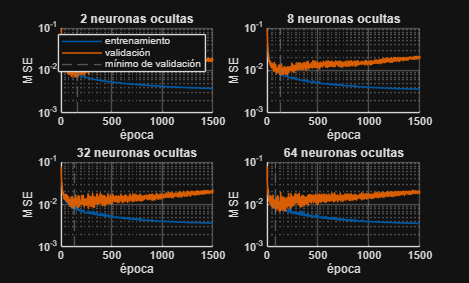


figure; colororder(paleta)
for h = 1:n_sobre
    subplot(2, ceil(n_sobre/2), h); hold on
    plot(curvas_sobre{h}.train, 'LineWidth', 1.2); plot(curvas_sobre{h}.val, 'LineWidth', 1.2)
    xline(R6.Epoca_val_minimo(h), '--', 'Color', paleta(6, :))
    title(sprintf('%s neuronas ocultas', mat2str(ocultas_sobre{h}))); grid on
    xlabel('época'); ylabel('MSE'); set(gca, 'YScale', 'log'); ylim([1e-3 1e-1])
    if h == 1, legend('entrenamiento', 'validación', 'mínimo de validación', 'Location', 'northeast'); end
end

## Funciones locales

MATLAB permite definir funciones locales al final de un script. No cambie los nombres ni los argumentos de entrada/salida.

function net = init_mlp(cfg)
    % Inicializa pesos y sesgos de todas las capas en la estructura `net`.
    net = struct();
    net.W = {};
    net.b = {};
    net.dW_prev = {};
    net.db_prev = {};
    layer_sizes = [cfg.n_inputs, cfg.hidden_layers, cfg.n_outputs];
    for k = 1:numel(layer_sizes) - 1
        net.W{k} = randn(layer_sizes(k+1), layer_sizes(k)) * cfg.init_scale;
        net.b{k} = zeros(layer_sizes(k+1), 1);
        net.dW_prev{k} = zeros(size(net.W{k}));
        net.db_prev{k} = zeros(size(net.b{k}));
    end
end

function [y, cache] = forward_mlp(net, x, cfg)
    % Propaga la entrada x a través de todas las capas de la red.
    a{1} = x;
    L = numel(net.W);
    for k = 1:L
        netv{k} = net.W{k} * a{k} + net.b{k};
        if k == L
            a{k+1} = activation(netv{k}, cfg.act_output);
        else
            a{k+1} = activation(netv{k}, hidden_act(cfg, k));
        end
    end
    y = a{end};
    cache.a = a;
    cache.netv = netv;
end

function tipo = hidden_act(cfg, k)
    % Activación de la capa oculta k, una para todas o una por capa si act_hidden es celda.
    if iscell(cfg.act_hidden), tipo = cfg.act_hidden{k}; else, tipo = cfg.act_hidden; end
end

function net = backward_mlp(net, cache, x, d, cfg)
    % Calcula los delta de cada capa y actualiza los pesos (ver fórmulas
    % de la Sección 1 de este mismo script).
    L = numel(net.W);
    delta = cell(1, L);
    delta{L} = (d - cache.a{L+1}) .* activation_deriv(cache.netv{L}, cfg.act_output);
    for k = L-1:-1:1
        delta{k} = (net.W{k+1}' * delta{k+1}) .* activation_deriv(cache.netv{k}, hidden_act(cfg, k));
    end
    for k = 1:L
        dW = cfg.eta * delta{k} * cache.a{k}' + cfg.momentum * net.dW_prev{k};
        db = cfg.eta * delta{k} + cfg.momentum * net.db_prev{k};
        net.W{k} = net.W{k} + dW;
        net.b{k} = net.b{k} + db;
        net.dW_prev{k} = dW;
        net.db_prev{k} = db;
    end
end

function y = activation(net_in, tipo)
    switch tipo
        case 'sigmoid'
            y = 1 ./ (1 + exp(-net_in));
        case 'tanh'
            y = tanh(net_in);
        case 'relu'
            y = max(0, net_in);
        case 'linear'
            y = net_in;
        otherwise
            error('Función de activación no reconocida: %s', tipo);
    end
end

function dy = activation_deriv(net_in, tipo)
    % Derivada de la función de activación, evaluada en net_in.
    switch tipo
        case 'sigmoid'
            f = 1 ./ (1 + exp(-net_in));
            dy = f .* (1 - f);
        case 'tanh'
            dy = 1 - tanh(net_in).^2;
        case 'relu'
            dy = double(net_in > 0);
        case 'linear'
            dy = ones(size(net_in));
        otherwise
            error('Función de activación no reconocida: %s', tipo);
    end
end

function [net, hist] = train_mlp(Xtr, Dtr, Xva, Dva, cfg)
    % Mismo ciclo de la sección 8, con error de validación por época y parada
    % temprana cuando la validación lleva cfg.patience épocas sin mejorar.
    % Sin conjunto de validación la paciencia vigila el error de entrenamiento.
    if iscell(cfg.act_hidden)
        assert(numel(cfg.act_hidden) == numel(cfg.hidden_layers), 'act_hidden debe tener una activación por capa oculta');
    end
    rng(cfg.seed);
    net = init_mlp(cfg);
    hist.train = zeros(cfg.max_epochs, 1);  hist.val = hist.train;
    mejor = Inf;  sin_mejora = 0;  mejor_net = net;  mejor_epoca = 0;
    for epoch = 1:cfg.max_epochs
        for p = randperm(size(Xtr, 1))
            [~, cache] = forward_mlp(net, Xtr(p, :)', cfg);
            net = backward_mlp(net, cache, Xtr(p, :)', Dtr(p, :)', cfg);
        end
        hist.train(epoch) = mse_mlp(net, Xtr, Dtr, cfg);
        if ~isempty(Xva), hist.val(epoch) = mse_mlp(net, Xva, Dva, cfg); end
        if hist.train(epoch) <= cfg.target_error, break; end
        if cfg.patience > 0
            if isempty(Xva), vigilado = hist.train(epoch); else, vigilado = hist.val(epoch); end
            if vigilado < mejor
                mejor = vigilado;  sin_mejora = 0;  mejor_net = net;  mejor_epoca = epoch;
            else
                sin_mejora = sin_mejora + 1;
                if sin_mejora >= cfg.patience, break; end
            end
        end
    end
    hist.convergio = hist.train(epoch) <= cfg.target_error;
    if cfg.patience > 0 && ~hist.convergio
        net = mejor_net;
    else
        mejor_epoca = epoch;
    end
    hist.train = hist.train(1:epoch);  hist.val = hist.val(1:epoch);
    hist.epochs = epoch;  hist.best_epoch = mejor_epoca;
end

function e = mse_mlp(net, X, D, cfg)
    % Error cuadrático medio de la red sobre un conjunto, patrones por filas.
    Y = forward_mlp(net, X', cfg);
    e = mean(0.5 * sum((D' - Y).^2, 1));
end

function clase = predict_mlp(net, X, cfg)
    % Clase predicha, por el umbral de cfg con una salida o por la mayor salida con varias.
    Y = forward_mlp(net, X', cfg);
    if cfg.n_outputs == 1
        clase = double(Y' >= cfg.threshold);
    else
        [~, clase] = max(Y, [], 1);  clase = clase';
    end
end

function acc = accuracy_mlp(net, X, D, cfg)
    acc = 100 * mean(predict_mlp(net, X, cfg) == D);
end

function [X, D] = xor_data(n_inputs)
    % Tabla de verdad de la XOR de n entradas, salida 1 con un número impar de unos.
    X = zeros(2^n_inputs, n_inputs);
    for p = 0:2^n_inputs - 1
        X(p+1, :) = bitget(p, n_inputs:-1:1);
    end
    D = mod(sum(X, 2), 2);
end

function T = onehot(D, n_clases)
    T = double(D == 1:n_clases);
end

function [X, D] = load_dataset(nombre, cfg)
    % Carga cada conjunto con la clase como entero desde 1, o 0 y 1 si es binaria.
    switch nombre
        case 'iris'
            M = load(cfg.datos.iris);  X = M(:, 1:4);  D = M(:, 5);
        case 'wine'
            M = readmatrix(cfg.datos.wine, 'FileType', 'text');  X = M(:, 2:end);  D = M(:, 1);
        case 'wdbc'
            T = readtable(cfg.datos.wdbc, 'FileType', 'text', 'ReadVariableNames', false);
            X = T{:, 3:end};  D = double(strcmp(T{:, 2}, 'M'));
        case 'banknote'
            M = readmatrix(cfg.datos.banknote);  X = M(:, 1:4);  D = M(:, 5);
        otherwise
            error('Conjunto desconocido: %s', nombre);
    end
end

function [Xtr, Dtr, Xte, Dte] = split_dataset(X, D, train_ratio, seed)
    % Misma partición del Taller 1, mezcla con semilla y corte por proporción.
    rng(seed);
    n = size(X, 1);
    idx = randperm(n);
    n_train = round(train_ratio * n);
    Xtr = X(idx(1:n_train), :);      Dtr = D(idx(1:n_train), :);
    Xte = X(idx(n_train+1:end), :);  Dte = D(idx(n_train+1:end), :);
end

function [Xtr, Dtr, Xva, Dva, Xte, Dte] = split_train_val_test(X, D, train_ratio, cfg)
    % Parte en entrenamiento y prueba con la proporción pedida, aparta de la parte
    % de entrenamiento la fracción de validación y escala todo con el entrenamiento.
    [Xtr, Dtr, Xte, Dte] = split_dataset(X, D, train_ratio, cfg.seed);
    [Xtr, Dtr, Xva, Dva] = split_dataset(Xtr, Dtr, 1 - cfg.val_fraction, cfg.seed + 1);
    [~, Xva] = scale_minmax(Xtr, Xva);
    [Xtr, Xte] = scale_minmax(Xtr, Xte);
end

function [Xtr, Xte] = scale_minmax(Xtr, Xte)
    % Escala cada columna al rango 0 a 1 con los mínimos y máximos del entrenamiento.
    mn = min(Xtr);  mx = max(Xtr);  mx(mx == mn) = mn(mx == mn) + 1;
    Xtr = (Xtr - mn) ./ (mx - mn);
    Xte = (Xte - mn) ./ (mx - mn);
end

function [W, b, epochs_to_converge] = train_perceptron(X, D, cfg)
    % Perceptrón del Taller 1, regla 3, sin cambios.
    W = randn(1, cfg.n_inputs) * cfg.init_scale;  b = randn(1) * cfg.init_scale;
    epochs_to_converge = cfg.max_epochs;
    for epoch = 1:cfg.max_epochs
        n_errors = 0;
        for p = 1:size(X, 1)
            y = double(W * X(p, :)' + b >= cfg.threshold);
            if y ~= D(p), n_errors = n_errors + 1; end
            W = W + cfg.alpha * (D(p) - y) * X(p, :);
            b = b + (D(p) - y);
        end
        if n_errors == 0, epochs_to_converge = epoch; break; end
    end
end

function [W, b, mse_hist] = train_adaline(X, D, cfg)
    % Adaline del Taller 1, Regla Delta sobre la salida lineal, sin cambios.
    W = randn(1, cfg.n_inputs) * cfg.init_scale;  b = randn(1) * cfg.init_scale;
    mse_hist = zeros(cfg.max_epochs, 1);
    for epoch = 1:cfg.max_epochs
        epoch_error = 0;
        for p = 1:size(X, 1)
            y = W * X(p, :)' + b;
            W = W + cfg.alpha * (D(p) - y) * X(p, :);
            b = b + cfg.alpha * (D(p) - y);
            epoch_error = epoch_error + 0.5 * (D(p) - y)^2;
        end
        mse_hist(epoch) = epoch_error / size(X, 1);
        if mse_hist(epoch) <= cfg.target_mse, mse_hist = mse_hist(1:epoch); break; end
    end
end

function acc = accuracy_of(X, D, W, b, threshold)
    acc = 100 * mean(double(X * W' + b >= threshold) == D);
end

function [acc, epocas] = one_vs_rest(Xtr, Dtr, Xte, Dte, cfg, modelo)
    % Una neurona por clase cuando hay más de dos, decisión por la mayor suma ponderada.
    clases = unique(Dtr);
    if numel(clases) == 2
        rng(cfg.seed);
        if strcmp(modelo, 'perceptron')
            [W, b, epocas] = train_perceptron(Xtr, Dtr, cfg);
        else
            [W, b, mse_hist] = train_adaline(Xtr, Dtr, cfg);  epocas = numel(mse_hist);
        end
        acc = accuracy_of(Xte, Dte, W, b, cfg.threshold);
        return
    end
    Z = zeros(size(Xte, 1), numel(clases));  epocas = 0;
    for c = 1:numel(clases)
        rng(cfg.seed);
        if strcmp(modelo, 'perceptron')
            [W, b, ep] = train_perceptron(Xtr, double(Dtr == clases(c)), cfg);
        else
            [W, b, mse_hist] = train_adaline(Xtr, double(Dtr == clases(c)), cfg);  ep = numel(mse_hist);
        end
        Z(:, c) = Xte * W' + b;  epocas = max(epocas, ep);
    end
    [~, pred] = max(Z, [], 2);
    acc = 100 * mean(clases(pred) == Dte);
end